# Distance to wall detection

Program using the robotics system toolbox to simulate a LIDAR

clear; clc; close;

load exampleMaps.mat

chosenMap = complexMap;

map = binaryOccupancyMap(chosenMap);
show(map)
alpha = pi/4;
loc = randLoc(chosenMap);
orient = rand*2*pi;
vehiclePose = [loc, orient]

vehiclePose =     8.5000   28.5000    0.2000


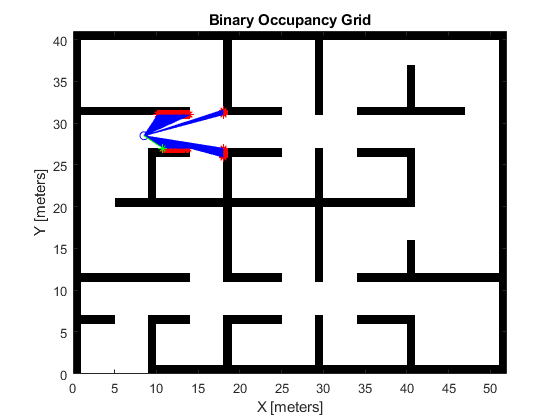

minDist = 2.7148


minDist = distDetec(map, alpha, vehiclePose)

function loc = randLoc(map)
    isFree = false;
    sizeMap = size(map);
    while ~isFree
        % inversion de dimensions entre matrice et binaryMap
        loc = [randi([1, sizeMap(2)]) randi([1, sizeMap(1)])];
        transform = changeRepere(loc, sizeMap);
        % vérifie si l'endroit d'apparition est libre
        if map(transform(1), transform(2))==0
            isFree = true;
        end
    end
    % -0.5 sur chaque coordonnée pour ne pas apparaître collé à un mur
    loc = loc-0.5;
end

function transform = changeRepere(loc, sizeMap)
    % si loc vaut [3 2] => checker valeur [hauteur-1 3]
    % si loc vaut [largeur hauteur-2] => checker valeur [3 largeur]
    % si loc vaut [x y] => checker valeur [hauteur-(y-1) x]
    x = loc(1);
    y = loc(2);
    transform = [sizeMap(1)-(y-1) x];
end

function minDist = distDetec(map, alpha, vehiclePose)
    maxrange = 10;
    alphaMax = alpha;
    alphaMin = -alphaMax;
    angles = [];
    sampleNb = 0;
    % Le LIDAR de la Qcar a une détection d'objets tous les 0.5°
    for i = alphaMin:deg2rad(0.5):alphaMax
        angles = [angles i];
        sampleNb = sampleNb + 1;
    end
    intsectionPts = rayIntersection(map,vehiclePose,angles,maxrange);
    
    % Affichage des rayons touchant un mur
    hold on
    plot(intsectionPts(:,1),intsectionPts(:,2),'*r') % Intersection points
    plot(vehiclePose(1),vehiclePose(2),'ob') % Vehicle pose
    for i = 1:sampleNb
        plot([vehiclePose(1),intsectionPts(i,1)],...
            [vehiclePose(2),intsectionPts(i,2)],'-b') % Plot intersecting rays
    end
    
    % Recherche de la distance minimale
    intsectionRelative = [intsectionPts(:,1)-vehiclePose(1) intsectionPts(:,2)-vehiclePose(2)];
    intsectionDist = sqrt(intsectionRelative(:,1).^2 + intsectionRelative(:,2).^2);
    [minDist, idMin] = min(intsectionDist,[],1,'linear');
    
    %Plot dist minimale
     plot(intsectionPts(idMin,1),intsectionPts(idMin,2),'*g')
      plot([vehiclePose(1),intsectionPts(idMin,1)],...
            [vehiclePose(2),intsectionPts(idMin,2)],'-g')
end